**HOW_TO_MATLAB**:  This is an example of how to use MATLAB in Analytics. MATLAB is a powerful tool for developing AI models using cutting-edge techniques.  In this example, we will explore how to choose the appropiate split predictor selection technique for out dataset when growing a random forest of regression trees. 

***Section 1: Load and Preprocess Data:***

We will work the *carbig* dataset which contains the number of cylinders, engine displacement, horsepower, weight, acceleration, model year, and country of origin of 406 vehicles.

The first step is load the dataset and then generates a MATLAB table. This table contains the predictor and response values for each observation. In this example, the response variable is the energy consumption of the vehicle expressed in miles per gallon (MPG)

load carbig %load the dataset

Cylinders = categorical(Cylinders) %Cylinder is categorical

Cylinders = 406×1 categorical array
     8 
     8 
     8 
     8 
     8 
     8 
     8 
     8 
     8 
     8 
     4 
     8 
     8 
     8 
     8 
     8 
     8 
     8 
     8 
     8 
     4 
     6 
     6 
     6 
     4 
     4 
     4 
     4 
     4 
     4 


Model_Year = categorical(Model_Year) % Model year is categorical

Model_Year = 406×1 categorical array
     70 
     70 
     70 
     70 
     70 
     70 
     70 
     70 
     70 
     70 
     70 
     70 
     70 
     70 
     70 
     70 
     70 
     70 
     70 
     70 
     70 
     70 
     70 
     70 
     70 
     70 
     70 
     70 
     70 
     70 


Origin = categorical(cellstr(Origin)) % Origin: String variable

Origin = 406×1 categorical array
     USA 
     USA 
     USA 
     USA 
     USA 
     USA 
     USA 
     USA 
     USA 
     USA 
     France 
     USA 
     USA 
     USA 
     USA 
     USA 
     USA 
     USA 
     USA 
     USA 
     Japan 
     USA 
     USA 
     USA 
     Japan 
     Germany 
     France 
     Germany 
     Sweden 
     Germany 



% Create a MATLAB table. This is like a dataframe in Python or R
X = table(Cylinders,Displacement,Horsepower,Weight,Acceleration,Model_Year,Origin,MPG);
head(X) % Similar to R, we could use 'head' to visualize a sample of the table

ans = 8×8 table
    Cylinders    Displacement    Horsepower    Weight    Acceleration    Model_Year    Origin    MPG
    _________    ____________    __________    ______    ____________    __________    ______    ___

        8            307            130         3504           12            70         USA      18 
        8            350            165         3693         11.5            70         USA      15 
        8            318            150         3436           11            70         USA      18 
        8            304            150         3433           12            70         USA      16 
        8            302            140         3449         10.5            70         USA      17 
    

***Section 2: Determine Leves in Predictors***

The regression tree algorithm tends to split predictors with many unique values (levels), e.g. continuos variables, over those with fewer levels, e.g. categorical variables. For each predictor, we can count the number of levels by using the function **countLevels. **This function:

- Converts the array to the categorical data type using the function *categorical.*

- Determines all unique categories while ignoring missing values using the function *categories.*

- Counts the number of categories using the function *numel*. 

countLevels = @(x) numel(categories(categorical(x))); %Creating the function.

Now, it is important to use the function *varfun* to apply our previous function countLevels to the predictor columns of out dataframe X and save the results. To do this we will create a new varaible call *numLevels. * Set the 'OutputFormat' property to 'uniform':

numLevels = varfun(countLevels,X); %creating a new varaible to store the results of our function countLevels

Then, we can create a barchart to compare the number of levels for each of the seven predictors

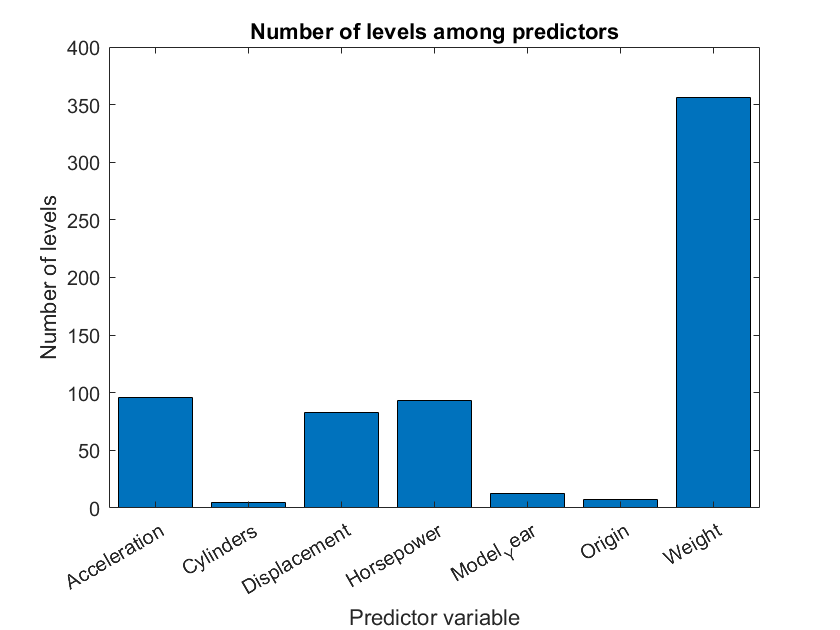

% Create the barchart
x_label = categorical(X.Properties.VariableNames(1:end-1)); % We need a vector with the column names
y_numbers = table2array(numLevels(1,1:end-1)); % Same for the values of each column
bar(x_label,y_numbers) % Using the function bar
title('Number of levels among predictors')
xlabel('Predictor variable')
ylabel('Number of levels')

The continuous variables have more levels than the categorical attributes. The number of levels among the predictors varies so much. Given this, the use of the standar regression trees to select split predictors at each tree node in a random forest can yield inaccurate predictor importance estimates.

***Section 3: Train Bagged Ensemble of Regression Trees.***

It is time to train a bagged ensemble of 200 regression trees to estimate predictor importance values. In this part, we can define a treer learner using the function *templateTree. *When called without any arguments, t = templateTree, the function returns a default decision-tree-learner-template suitable for a training an ensemble.

Within this function we apply the following properties and values:

- Set `'NumVariablesToSample' `to `'all'` — This option enforces that all predictors are used for each split. 

- Set `'PredictorSelection'` to `'interaction-curvature'` — This option selects the algorithm used to select the best predictor at each node

- Set `'Surrogate'` to `'on'` —  Since the data set includes missing values, this option specifies that the tree uses surrogate splits to increase accuracy.

t = templateTree('NumVariablesToSample','all','PredictorSelection','interaction-curvature','Surrogate','on');

Now it is time to create an ensemble regression tree model `Mdl` usint the `fitrensemble` function and the three template t. Train on the data in the table X, where the response column is 'MPG'. Use a bootstrap aggregation method with 200 learning cycles.

Mdl = fitrensemble(X,'MPG','Learners',t,'NumLearningCycles',200);
Mdl

Mdl =   RegressionEnsemble
           PredictorNames: {'Cylinders'  'Displacement'  'Horsepower'  'Weight'  'Acceleration'  'Model_Year'  'Origin'}
             ResponseName: 'MPG'
    CategoricalPredictors: [1 6 7]
        ResponseTransform: 'none'
          NumObservations: 398
               NumTrained: 200
                   Method: 'LSBoost'
             LearnerNames: {'Tree'}
     ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                  FitInfo: [200×1 double]
       FitInfoDescription: {2×1 cell}
           Regularization: []


  Properties, Methods


Finally, we use our `Mdl` model and the MATLAB function obbPredict to calculate the ensemble prediction `yhat` and the estimate model $R^2$

yHat = predict(Mdl,Mdl.X);
R2 = corr(Mdl.Y,yHat)^2

R2 = 0.9403

***Section 4: Predictor Importance Estimation***